%path = "C:\Users\miech\OneDrive - Politechnika Warszawska\PMT-badanie\C1--hv--final00--00000samples.csv";
%path = "C:\Users\miech\Documents\HyperK\Dane\JMarzec\CFD\C1--hv--10700---00000samples.csv";
path = "C:\Users\mnurek\Documents\HK\Dane\JMarzec\CFD\C1--hv--10700---00000samples.csv";
pmt_data = csvread(path);
pmt_data = pmt_data';

waveforms = pmt_data(:,1);
waveform_len = length(waveforms);
amplitudes = get_amplitudes(waveforms);

% Filter <0.3PE pulses
waveforms = waveforms(:,max(waveforms) > 0.01);
amplitudes = amplitudes(:,amplitudes > 0.01);
% less_than_03_pe_indices = amplitudes < 0.01;
% for n = 1 : length(less_than_03_pe_indices)
%     waveforms(:,n) = [];
% end

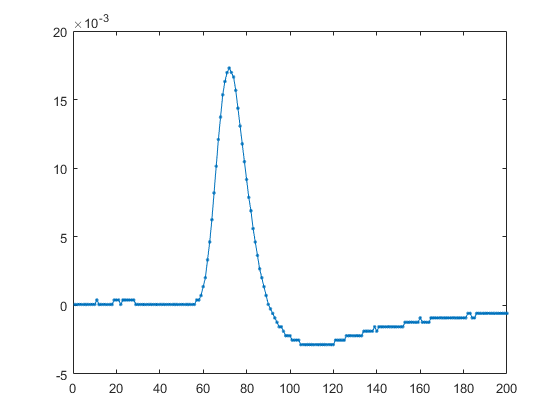

plot(1:waveform_len, waveforms, ".-")

% FFT interpolation of original waveform
brb_interpolation_factor = 4; %Ts 8ns -> 2ns

interpolation_factor = 25; %Ts 2ns -> 80ps
interpolated_waveform = interpft(waveforms,waveform_len * interpolation_factor);
interpolated_waveform_len = length(interpolated_waveform);

final_interpolation_factor = brb_interpolation_factor*interpolation_factor;

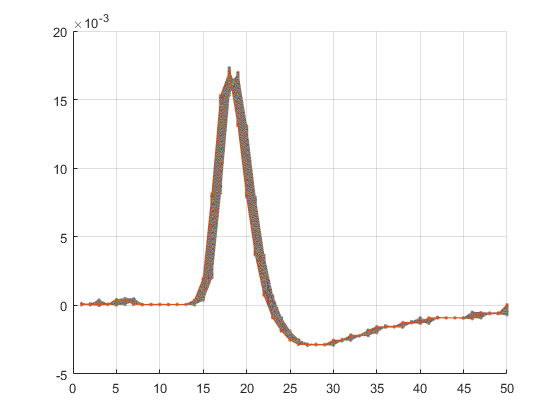

% Get amplitude paramater for different Ts 8ns waveforms
amplitude_parameters = zeros(1 * final_interpolation_factor, size(interpolated_waveform, 2));
figure; hold on; grid on;
for k = 1 : size(interpolated_waveform, 2)
    for n = 1 : 1 * final_interpolation_factor
        current_waveform = interpolated_waveform(n:final_interpolation_factor:interpolated_waveform_len, k);
        amplitude_parameters(n,k) = get_amplitude_parameter(current_waveform);
        plot(1:length(current_waveform), current_waveform, ".-")
    end
end

hold off;

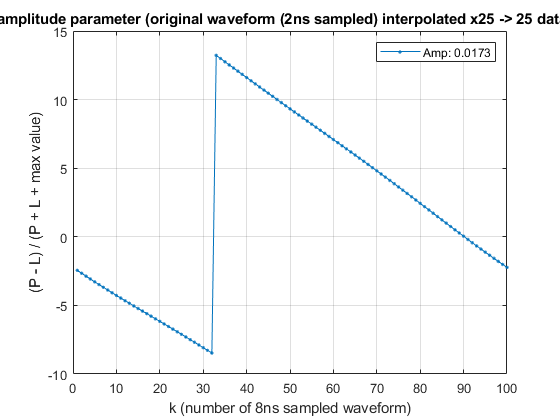

plot(1:length(amplitude_parameters), amplitude_parameters ./ amplitudes, ".-"); grid on;
title("peak amplitude parameter (original waveform (2ns sampled) interpolated x25 -> 25 data points)")
ylabel("(P - L) / (P + L + max value)")
xlabel("k (number of 8ns sampled waveform)")
legendLabels = "Amp: " + string(amplitudes);
legend(legendLabels)

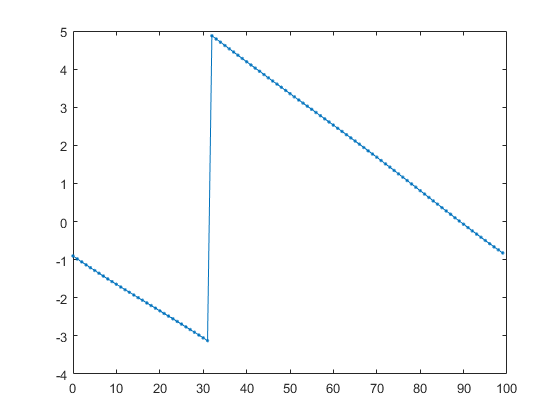

time_shift = amplitude_parameters * 8 ./ (max(amplitude_parameters) - min(amplitude_parameters));
plot(0:length(time_shift) - 1, time_shift, ".-")

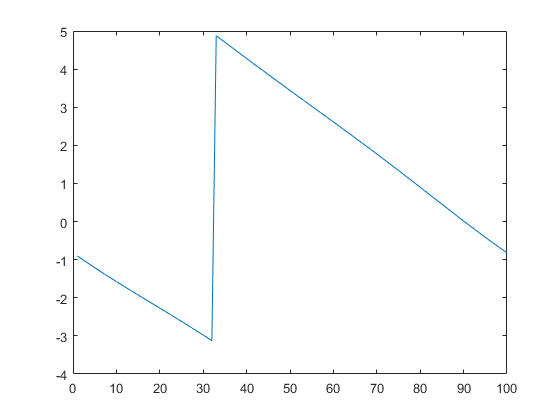

amplitude_parameters_normalized = amplitude_parameters ./ amplitudes;
time_shift_normalized = amplitude_parameters_normalized * 8 ./ (max(amplitude_parameters_normalized) - min(amplitude_parameters_normalized));
plot(time_shift_normalized)

% Calculate absolute error values for max_time
max_time_values = time_shift(end,:);

% Calculate CFD using algorithm
[cf_time_ns, cr, amplitude_cr, amplitude_max, samples_intergral, cr_idx, cf_time_coarse, cf_time_min] = calculate_time_cf_brb(waveforms(:,1));


% Function to retrieve the fs = 8 ns waveform from original delayed by k
% original samples
x1 = 1:4:waveform_len;
x2 = 2:4:waveform_len;
x3 = 3:4:waveform_len;
x4 = 4:4:waveform_len;
plot(x1, waveforms(x1), ".")

function [amplitudes] = get_amplitudes(waveforms)
    amplitudes = max(waveforms);
end
function [amplitude_parameter] = get_amplitude_parameter(waveform)
    % Find maximum index for waveform
    [max_value, max_index] = max(waveform);
    
    L1_index = max_index - 1;
    L2_index = max_index - 2;
    P1_index = max_index + 1;
    P2_index = max_index + 2;
    L = waveform(L1_index) + waveform(L2_index);
    P = waveform(P1_index) + waveform(P2_index);
    sum_in_peak = L + P + max_value;
    amplitude_parameter = (P - L) / sum_in_peak;
end